Data import from table and handle creation for further use.

Traw    = readtable('Exercise\Exercise1_RNAseq_Analysis\data\Saccharomyces_RNAseq_RAW_counts.csv');
Factors = Traw(:,2:end).Properties.VariableNames;
ref     = startsWith(Factors,'Control');
Htemp   = startsWith(Factors,'HighT');
LowpH   = startsWith(Factors,'LowPH');
Osmo    = startsWith(Factors,'Osmo');
Anae    = startsWith(Factors,'Anae');

***1.a)**** How many genes are represented in your dataset? *

disp(length(Traw.GeneName));

        7126



***1.b) ****How many biological replicates per experimental conditions were obtained in this study?*

disp(Traw.Properties.VariableNames);

  Columns 1 through 6

    {'GeneName'}    {'Control_Rep1'}    {'Control_Rep2'}    {'Control_Rep3'}    {'HighTemperature…'}    {'HighTemperature…'}

  Columns 7 through 12

    {'HighTemperature…'}    {'LowPH_Rep1'}    {'LowPH_Rep2'}    {'LowPH_Rep3'}    {'OsmoPressure_Rep1'}    {'OsmoPressure_Rep2'}

  Columns 13 through 16

    {'OsmoPressure_Rep3'}    {'Anaerobic_Rep1'}    {'Anaerobic_Rep2'}    {'Anaerobic_Rep3'}



`As can be seen, there are 16 total columns, with one being the Gene Names. There are 5 different conditions with 3 replicates each, making 15 total data columns.`

`1c)` *How many genes were actually measured by RNAseq (non-zero reads)?*

numOnly    = Traw{:,2:end}; %Creates an array without GeneNames
Referance  = geomean(numOnly,2); %Creates referance array with one column
NaN=Referance > 0; %Creates new array with 1 when cell is above 0 and 0 if it is 0 (or below)
ratios     = numOnly(NaN,:)./Referance(NaN); %Array with only non-zero reads
disp(nnz(all(ratios,2)))

        5950



***1d)**** Normalize your read counts dataset, by first dividing the values by the mean expression level of each gene across samples, and then dividing each library (column) by the median of its previously normalized values.*

Size       = median(ratios,1); %Size Factors for all columns
normCounts = numOnly./Size; %Normalizes all columns by their respective size factor

***1e) ****Visualize your read counts distributions using boxplots for the transformed log2 values (before and after normalization). What can you say about your dataset in terms of spanning (orders of magnitude), median expression values? Are there any evident effects on the dataset with the proposed normalization method? If so, try to explain them.*

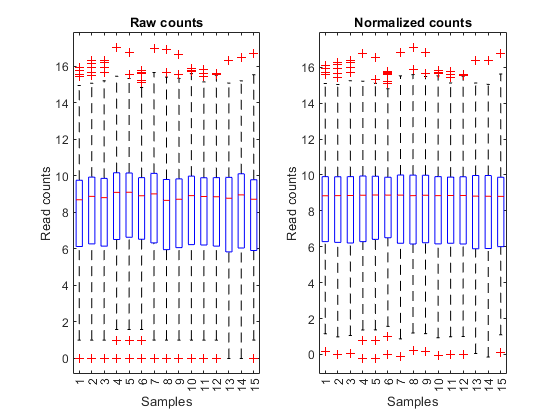

lognum = log2(numOnly);
lognormCounts = log2(normCounts);

subplot(1,2,1);
boxplot(lognum)
title('Raw counts')
ylabel('Read counts')
xlabel('Samples')

subplot(1,2,2);
boxplot(lognormCounts)
title('Normalized counts')
ylabel('Read counts')
xlabel('Samples')

Before looking at the boxplots and interpreting them, one observation about the plots is that there seems to be far too few outliers compared to the numbers of data plotted. Why this occurs is something I do not know the answer too. When plotting the non-zero version of the Log2 arrays, far more outliers can be seen. 

The differences in between the raw and normalized plots, however, are that the median becomes more uniform in the normalized plot while the order of magnitude remained mostly the same.

***2.**** Show your PCA results (PC1 vs PC2, displaying the percentage of variance for each in their respective axis labels).*

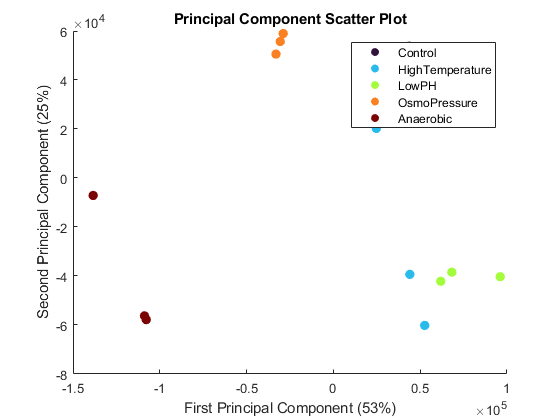

[pc,zscores,pcvars] = pca(normCounts'); %Performing the PCA
figure %Creates new figure window
colorScheme = colormap(turbo(5)); %Creating five different colors to differentiate between sample sets
hold on
condStr = {};
for i=1:5
    nameTMP = strsplit(Traw.Properties.VariableNames{(i-1)*3+2},'_');
    PC1     = zscores((i-1)*3+1:i*3,1);
    PC2     = zscores((i-1)*3+1:i*3,2);
    condStr = [condStr;nameTMP{1}];
    scatter(PC1,PC2,50,colorScheme(i,:),'fill');
end
percPC1 = round((pcvars(1)./sum(pcvars)).*100);
percPC2 = round((pcvars(2)./sum(pcvars)).*100);
xlabel(['First Principal Component ' ,'(',num2str(percPC1) , '%)']);
ylabel(['Second Principal Component ' ,'(',num2str(percPC2) , '%)']);
title('Principal Component Scatter Plot');
legend(condStr)
hold off

***2.a) ****Explain what the PCA results show.*

This type of plot displays overall differences between data sets, in terms of gene expression, on a 2D plane with the most significant and second most significant principal components.

***2.b) ****Are there any outlier samples in the dataset for any of the analyzed conditions?*

One of the Anaerobic tests is an outlier as it shows a large variance to the other two, tightly packed, tests. Furthermore, the high temeprature samples vary greatly on PC2.

***3. ****Show the number of differentially expressed genes reference and a stress condition of your choice (High temperature, low pH, osmotic pressure). Use absolute log2 fold-change = 2 and 0.01 corrected p-value as your threshold parameters.*

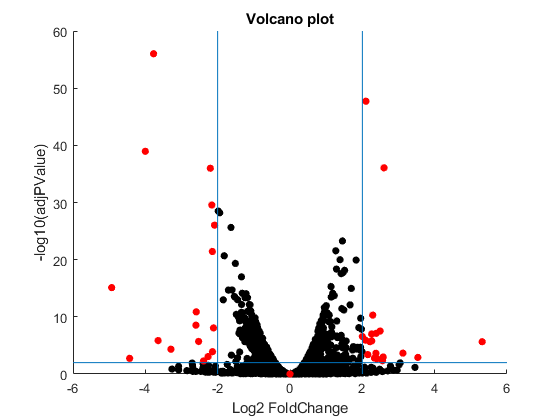

normCountsStress  = normCounts(:,Htemp);
normCountsref     = normCounts(:,ref);
tLocal = nbintest(normCountsref,normCountsStress,'VarianceLink','LocalRegression');
padj = mafdr(tLocal.pValue,'BHFDR',true);
meanRef    = mean(normCountsref,2);
meanStress = mean(normCountsStress,2);
log2FC     = log2(meanStress./meanRef);
geneTable  = table(meanRef,meanStress,log2FC,tLocal.pValue,padj);
geneTable.Properties.RowNames      = Traw.GeneName;
geneTable.Properties.VariableNames = {'Mean_Ref','Mean_Stress','Log2_FC','pVal','adjPVal'};

x=geneTable.Log2_FC; y=geneTable.adjPVal;
FClim=abs(x)>=2; adjlim=y<=0.01;y=-log10(geneTable.adjPVal);
figure
hold on
scatter(x,y,30,'fill','black')

% For loop to only include values on positions in the matrix where both
% conditions abs(Log2FC)=>2 and adj_pVal<=0.01 are true
for i=1:length(x)
    if adjlim(i)==1 && FClim(i)==1 %BOTH conditions means keep value
        x(i)=x(i);
        y(i)=y(i);
    else                           %Otherwise, put 0 
        x(i)=0;
        y(i)=0;
    end
end

scatter(x,y,30,'fill','red')
line([2 2],[0 60]); line([-2 -2],[0 60]); line([-6 6],-log10([0.01 0.01])); %Lines show cut-off points
title('Volcano plot')
xlabel('Log2 FoldChange')
ylabel('-log10(adjPValue)')
hold off

***3.a) ****Plot your results in a volcano plot, highlighting with a different color the differentially expressed genes. Explain in some lines how a volcano plot can be interpreted.*

Fold Change, denoted on the X-axis, is a measurement of the mean level of normalized expression between the stress condition and the normal condition. The adjusted p value, denoted on the Y-axis, is a measurement of the probability of the change occuring randomly. By infering -log10 on the adjusted P value, the genes of interests appear on the upper part of the plot, being more improbable to have been caused randomly with height on the plot.

***3.b) ****How many down and up regulated genes were obtained?*

disp(nnz(geneTable.Log2_FC >= 2 & geneTable.adjPVal <= 0.01))

    19



disp(nnz(geneTable.Log2_FC <= -2 & geneTable.adjPVal <= 0.01))

    17



disp(nnz(abs(geneTable.Log2_FC) >= 2 & geneTable.adjPVal <= 0.01))

    36



The test contains 19 up regulated and 17 down regulated genes, for a total of 36. It is important to note that the dataset contains all zero-reads, this leading to a higher number. Zero reads are normally not concidered into data analysis such as PCA, yet I decided to keep this in to show the difference to a non-zero PCA analysis (Mihail's file). 

***3.c) ****How are the results from these plots similar to or different from the results from the PCA plot?*

PCA plots show how different sample sets, with different conditions, vary and compare to eachother. A volcano plot shows individual genes, allowing for targeted analysis of said genes. 

***4. ****Explore your DE analysis results and combine them with gene descriptions information available in the exercise data subfolder (see the MATLAB script).*

***4.a) ****Provide the gene identifiers, names and functions for your top 10 differentially expressed genes. *

Table4 = geneTable; %In order to leave geneTable untouched
Desc=readtable('GeneDescriptions.csv'); %Get data as table
Desc=table(Desc{:,1}, Desc{:,3}); %Remove abundant second column, we only want gene names (for outerjoin) and description columns
q=Table4.Properties.RowNames; Table4{:,6}=q; %Adds row names to 6th column for outerjoin
Table4 = outerjoin(Desc,Table4,'LeftKeys','Var1','RightKeys','Var6'); %Adds Gene Descriptions to Genetable
Table4 = sortrows(Table4,'adjPVal','ascend');
Table4.Var6 = []; %Removes abundand column (which was only used for the purpose of outerjoin)
Table4.Properties.VariableNames([1 2]) = {'Gene','Description'}; %Adds headers to Gene names and Description columns
disp(Table4(1:10,:))

       Gene                   Description                Mean_Ref    Mean_Stress    Log2_FC       pVal        adjPVal  
    ___________    __________________________________    ________    ___________    _______    __________    __________

    {'YPL058C'}    {'Pleiotropic Drug Resistance'   }     3298.7       241.39       -3.7724     1.317e-60    9.3848e-57
    {'YJR094C'}    {'Inducer of MEiosis'            }     218.23       935.04        2.0992    5.4294e-52    1.9345e-48
    {'RDN5-1' }    {0×0 char                        }     286.75       17.914       -4.0006     4.635e-43     1.101e-39
    {'YPL187W'}    {'Mating Factor ALPHA'           }     59.777       362.09        2.5987    4.8592e-40    8.6566e-37
    {'YLL053C'}    {0×0 char             

***4.b) ****Can you infer any interesting/meaningful biological pattern from these top DE genes?*

Without having more insight into how these genes relate to one another (eg how far off their are in the biological pathways), it is hard to infer any biological pattern.

***5. ****GO terms analysis.*

***5.a) ****Provide the associated GO term IDs and descriptions for the top DE gene for your stress condition.*

GoTerms_table = readtable('../data/GoTermsMapping.txt','delimiter','\t');
GoTermsIDs    = unique(GoTerms_table.GoTerm);

GoTermsGeneMap = containers.Map();
for i = 1:height(GoTerms_table)
    key = GoTerms_table{i,'GeneName'}{1};
    if isKey(GoTermsGeneMap,key)
        GoTermsGeneMap(key) = [GoTermsGeneMap(key),GoTerms_table{i,'GoTerm'}{1}];
    else
        GoTermsGeneMap(key) = {GoTerms_table{i,'GoTerm'}{1}};
    end
end
fprintf('Number of annotated genes related to functional process is %d.\n',GoTermsGeneMap.Count)

Number of annotated genes related to functional process is 6439.


fprintf('Number of unique GO terms associated to annotated genes is %d.\n',numel(unique(GoTerms_table.GoTerm)))

Number of unique GO terms associated to annotated genes is 3187.


fprintf('Number of gene-GO term associations is %d.\n',numel(GoTerms_table))

Number of gene-GO term associations is 52862.


selectedGene      = Table4{1,1}{1,1}; %Picks out the top gene from the table created in step 4
associatedGoTerms = GoTermsGeneMap(selectedGene);
disp(['Associated GO Terms for gene ',selectedGene])

Associated GO Terms for gene YPL058C


disp(associatedGoTerms)

    {'GO:0055085'}    {'GO:0015849'}    {'GO:1903825'}    {'GO:0034220'}    {'GO:0035376'}




GO = geneont('File','../data/GoTerms.obo');
%This for loop will give discriptions for each GO associated with the
%selected gene
for i=1:length(associatedGoTerms)
GoTermID         = associatedGoTerms{i}(4:end);
GoTermName       = GO(str2double(GoTermID)).Terms.Name;
GoTermDefinition = GO(str2double(GoTermID)).Terms.Definition;

disp(['GO Term ',(GoTermID),' - ',GoTermName,' : ',GoTermDefinition])
end

GO Term 0055085 - transmembrane transport : "The process in which a solute is transported across a lipid bilayer, from one side of a membrane to the other." [GOC:dph, GOC:jid]
GO Term 0015849 - organic acid transport : "The directed movement of organic acids, any acidic compound containing carbon in covalent linkage, into, out of or within a cell, or between cells, by means of some agent such as a transporter or pore." [ISBN:0198506732]
GO Term 1903825 - organic acid transmembrane transport : "The process in which an organic acid is transported across a membrane." [GO_REF:0000069, GOC:TermGenie]
GO Term 0034220 - ion transmembrane transport : "A process in which an ion is transported across a membrane." [GOC:mah]
GO Term 0035376 - sterol import : "The directed movement of a sterol into a cell or organelle. Sterols are steroids with one or more hydroxyl groups and a hydrocarbon side-chain in the molecule." [GOC:bf, PMID:19793923]


***5.b) ****What can you learn from it? Compare the knowledge you got with the summary paragraph on the S. cerevisiae Genome Database.*

Judging by the results from the GoTerm analysis above, the gene of interest is associated with different transport mechanisms. The database yeastgenome.com gives the gene the description of being a "Plasma membrane ATP-binding cassette (ABC) transporter". Why this gene specifically would be so underexpressed during high temeperature, I cannot figure out.

***6. ****Find enriched GO terms in differentially expressed genes subset.*

***6.a) ****Take the first associated GO term for the top DE gene in the dataset, provide the number of DE genes that this GO term is also associated with. *

indexDE       = geneTable.adjPVal<=0.01 & abs(geneTable.Log2_FC)>=2;
geneListDE    = geneTable.Properties.RowNames(indexDE);
geneListNonDE = geneTable.Properties.RowNames(~indexDE);
rankedPosition = 1;
GoTermID       = str2double(associatedGoTerms{rankedPosition}(4:end));
top_gene=associatedGoTerms(:,1);
display(top_gene(1:1))

  1×1 cell array

    {'GO:0055085'}



full_GoTerm_Id = sprintf('GO:0055085');

GoTermsIDs_table  = GoTerms_table.GoTerm;
GoTermCountAll = 0;
GoTermCountDE  = 0;
presence       = find(strcmp(GoTermsIDs_table,full_GoTerm_Id));
if ~isempty(presence)
    relatedGenes  = GoTerms_table.GeneName(presence);
    [~,indexesDE] = intersect(geneListDE,relatedGenes);
    GoTermCountDE  = length(indexesDE);
    GoTermCountAll = length(presence);
end

disp(['GO Term ',num2str(GoTermID),' is in ',num2str(GoTermCountDE),...
    ' out of ',num2str(numel(geneListDE)),' DE Genes and in total there are ',...
    num2str(GoTermCountAll),' occurences in all ',num2str(numel(GoTermsGeneMap.keys)),' Genes'])

GO Term 55085 is in 5 out of 36 DE Genes and in total there are 250 occurences in all 6439 Genes


pHyperGeo=hygepdf(GoTermCountDE,numel(GoTermsGeneMap.keys),GoTermCountAll,numel(geneListDE));
disp(['The probablity for this is ',num2str(pHyperGeo)]);

The probablity for this is 0.0095766


***6.c) ****Provide a list of GO term IDs and descriptions for all the significantly enriched GO terms (adjusted p-Value <=0.01) in your DE genes.*

pValues=zeros(length(GoTermsIDs),1);
for i=1:length(pValues)
    GoTermCountAll=0;
    GoTermCountDE=0;
    presence=find(strcmp(GoTermsIDs_table,GoTermsIDs{i}));
    if ~isempty(presence)
        relatedGenes=GoTerms_table.GeneName(presence);
        [~,indexesDE] = intersect(geneListDE,relatedGenes);
        GoTermCountDE  = length(indexesDE);
        GoTermCountAll = length(presence);
    end
    pHyperGeo=hygepdf(GoTermCountDE,numel(GoTermsGeneMap.keys),GoTermCountAll,numel(geneListDE));
    pValues(i)=pHyperGeo;
end
pValuesAdj = mafdr(pValues,'BHFDR',true);
GoTermsTable = table(GoTermsIDs, pValuesAdj);
Enriched=GoTermsIDs(find(pValuesAdj<=0.01));
display(Enriched)


Enriched =

  0×1 empty cell array



pValuesAdj=sortrows(pValuesAdj,'ascend');
disp(pValuesAdj(1:10,:)); 

    0.0323
    0.0323
    0.0323
    0.0723
    0.2845
    0.9944
    0.9944
    0.9944
    0.9944
    0.9944



No adjusted P-values are below the threshold of 0.01 when using high temperature as the condition